clear; clc;

## get datacube

root_path = 'D:\files\spectral_analysis\mat_demo\data\raman';
seed_variety = 'zd958';
file_name0 = 125;
file_name = num2str(file_name0);

% file path
hdr_path_name = strcat(root_path, seed_variety, '\', file_name, '.hdr');
raw_path_name = strcat(root_path, seed_variety, '\', file_name, '.raw');

% get dimensions and waves
info = get_info(hdr_path_name);
[samples, lines, bands, wavelengths] = get_dimensions(info)

samples = 1024

lines = 638

bands = 1024

wavelengths = 	1.0e+03 *

    0.7321    0.7324    0.7327    0.7329    0.7332    0.7334    0.7337    0.7340    0.7342    0.7345    0.7347    0.7350    0.7353    0.7355    0.7358    0.7360    0.7363    0.7366    0.7368    0.7371    0.7373    0.7376    0.7378    0.7381    0.7384    0.7386    0.7389    0.7391    0.7394    0.7397    0.7399    0.7402    0.7404    0.7407    0.7410    0.7412    0.7415    0.7417    0.7420    0.7423    0.7425    0.7428    0.7430    0.7433    0.7436    0.7438    0.7441    0.7443    0.7446    0.7449


% raman shift
raman_shift = 10^7/785 - 10^7./wavelengths;

% get datacube

tic

rawdata = get_rawdata(raw_path_name);

rawcube0 = reshape(rawdata, [samples, bands, lines]); % contrast order to python
rawcube = permute(rawcube0, [3, 1, 2]);

toc

历时 0.989119 秒。


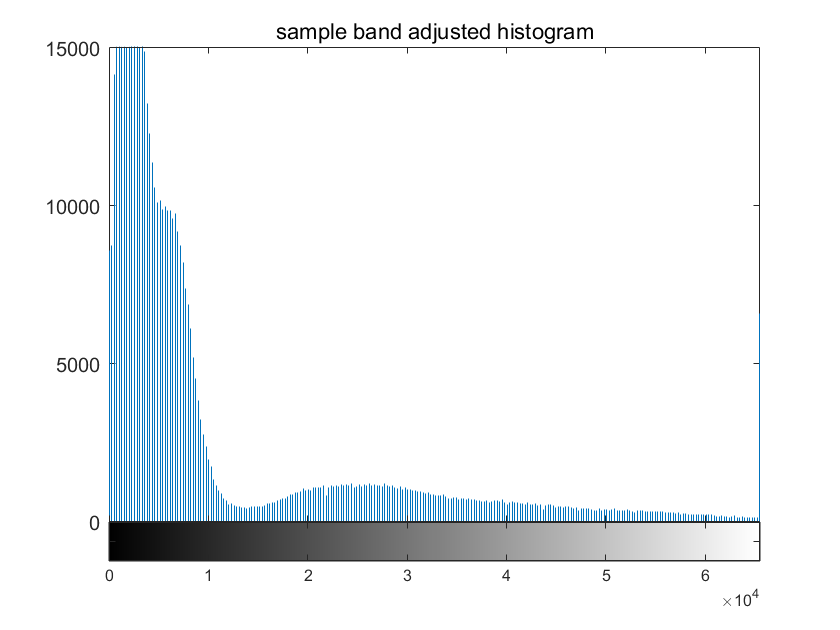

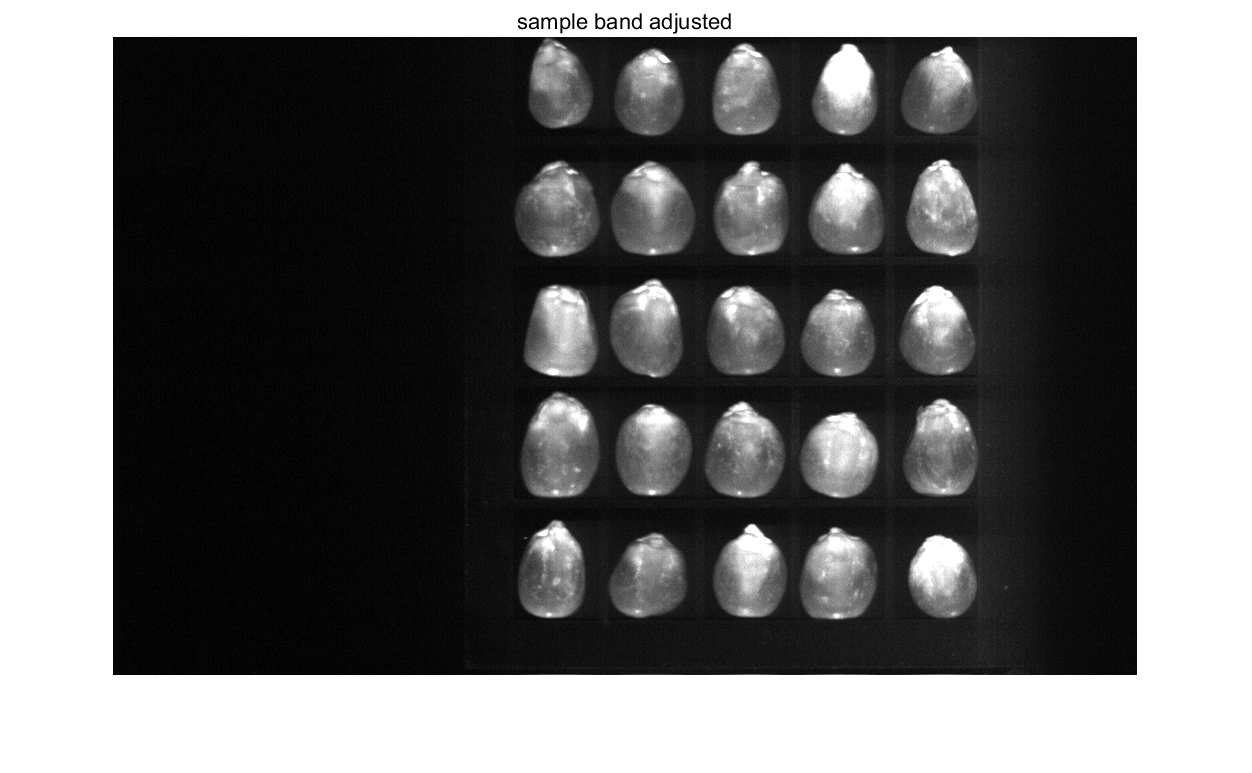

% band display  %% handi
display_band(rawcube, 500);

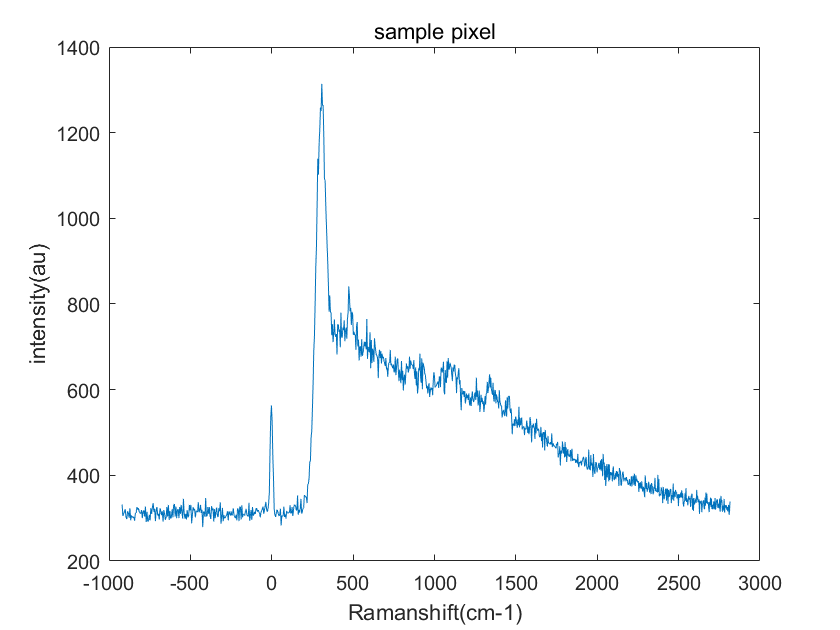

% pixel display %% handi
display_pixel(rawcube, raman_shift, 315, 610);

% effective raman shift 
[~, p1] = min(abs(raman_shift - 400));
[~, p2] = min(abs(raman_shift - 1800));
effshift = raman_shift(p1:p2);

% define effcube
effcube = rawcube(:, 400:870, p1:p2);
efflines = size(effcube, 1);
effsamples = size(effcube, 2);
effbands = size(effcube, 3);

## mask and roi

% effective band for mask
[~, b] = min(abs(effshift - 477))

b = 20

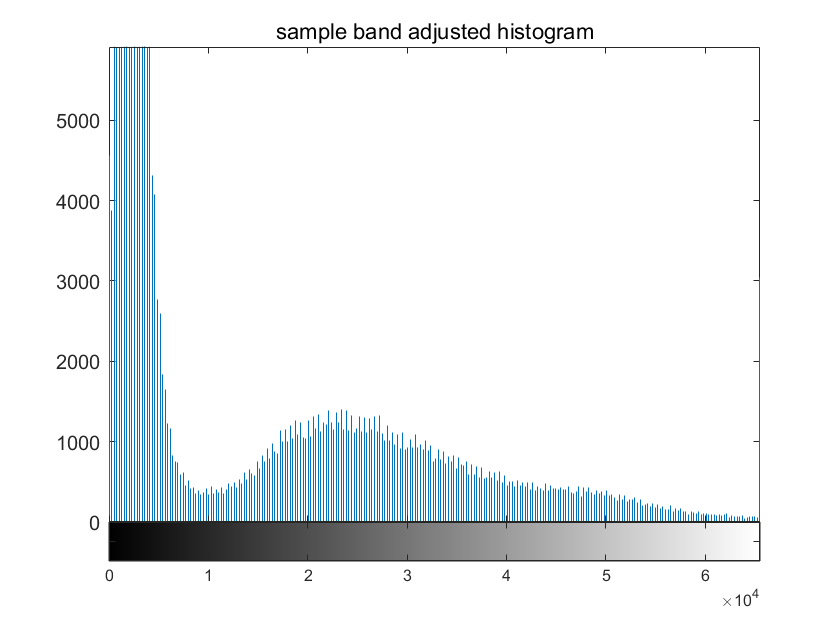

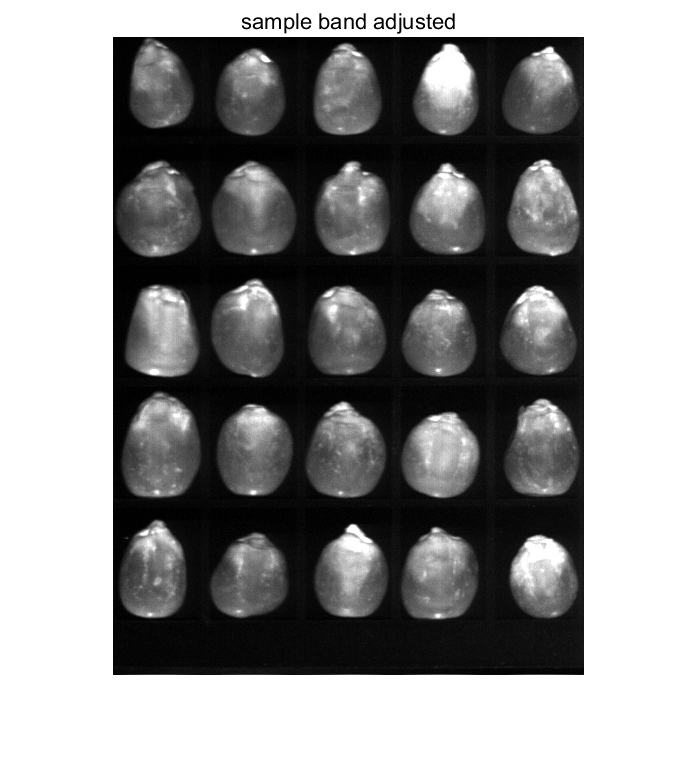

display_band(effcube, b);

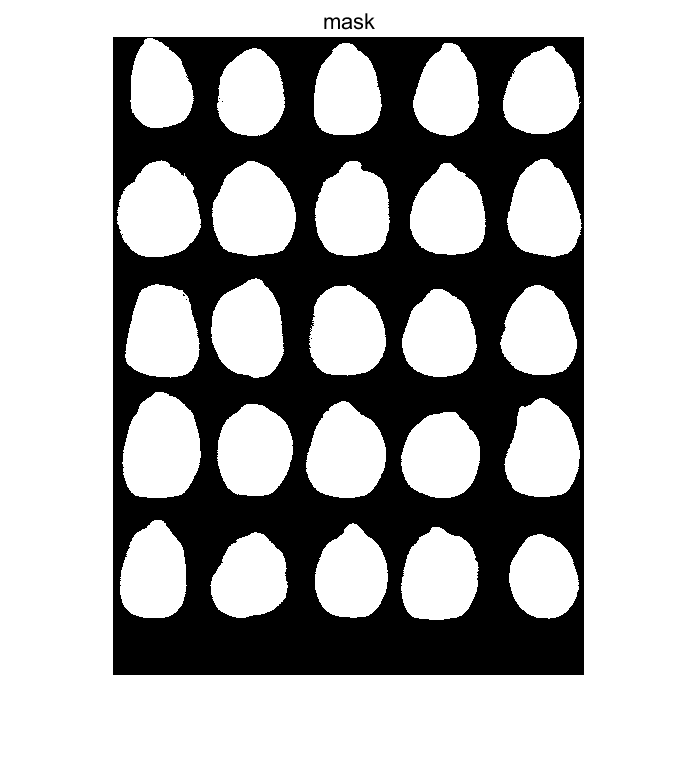

% mask  %% handi
bw = get_mask(effcube, b);
figure; imshow(bw); title('mask')

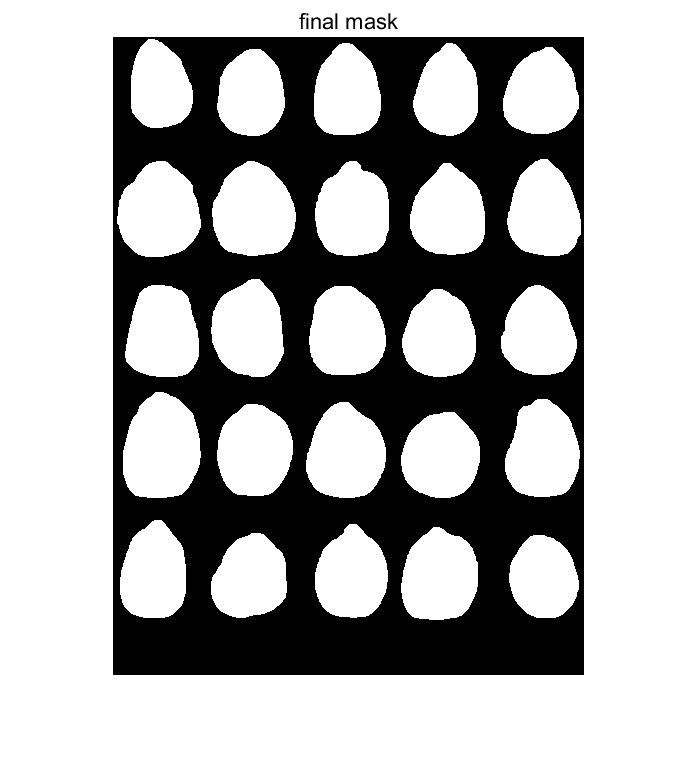

% morphology
se1 = strel('disk', 8);
se2 = strel('disk', 4);
bw_final = imopen(imclose(bw, se2), se1);
bw_final = bwareaopen(bw_final, 1000, 8);     
figure; imshow(bw_final); title('final mask')

% roi average data 
tic
[avedata, datalabel] = get_ave_spec(effcube, bw_final);
toc

历时 36.967032 秒。


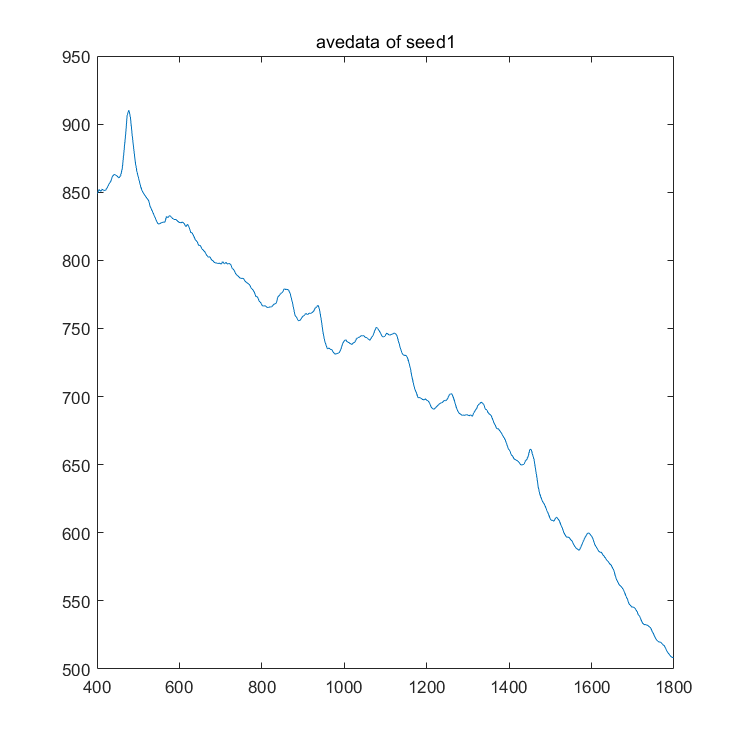

plot(effshift, avedata(1, :))
title('avedata of seed1')

## preprocessing ------ sgfilter

% sgfilter for noise
tic

cube_sgfilter = zeros(efflines, effsamples, effbands);

for i = 1:efflines
    X = zeros(effsamples, effbands);
    X(:, :) = effcube(i, :, :);
    X_sgfilter = pre_sgfilter(X);  %, 15, 2, 2
    cube_sgfilter(i, :, : ) = X_sgfilter(:, :);
end

toc

历时 7.142560 秒。


% roi data 
tic
avedata_sgfilter = get_ave_spec(cube_sgfilter, bw_final);
toc

历时 34.890769 秒。


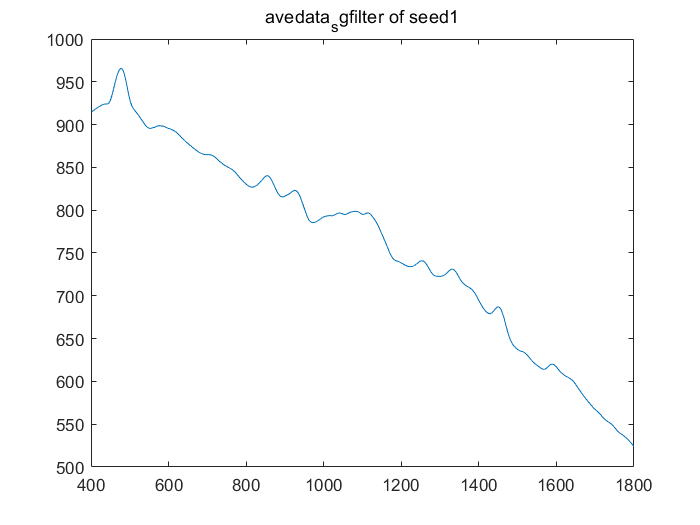

figure;

plot(effshift, avedata_sgfilter(1, :))
title('avedata_sgfilter of seed1')

## preprocessing ------ airpls

% airpls for background and baseline
tic

cube_sg_airpls = zeros(efflines, effsamples, effbands);
cube_background = zeros(efflines, effsamples, effbands);

for i = 1:efflines
    X = zeros(effsamples, effbands);
    X(:, :) = cube_sgfilter(i, :, :);
    
    [X_airpls, Z_airpls] = pre_airpls(X);
    
    cube_sg_airpls(i, :, : ) = X_airpls(:, :);
    cube_background(i, :, : ) = Z_airpls(:, :);
end

toc

历时 144.691321 秒。


% % pixel display %% handi
% 
% sample_pixel1 = reshape(effcube(320, 280, :), 1, effbands);
% sample_pixel2 = reshape(cube_sgfilter(320, 280, :), 1, effbands);
% sample_pixel3 = reshape(cube_sg_airpls(320, 280, :), 1, effbands);
% 
% figure;
% plot(effshift, sample_pixel1, "--"); title('raw')
% hold on;
% plot(effshift, sample_pixel2); title('sgfilter')
% hold on;
% plot(effshift, sample_pixel3); title('sg-airpls')

% roi data 
tic
avedata_sg_airpls = get_ave_spec(cube_sg_airpls, bw_final);
toc

历时 39.784097 秒。


% roi background 
tic
avedata_background = get_ave_spec(cube_background, bw_final);
toc

历时 34.809528 秒。


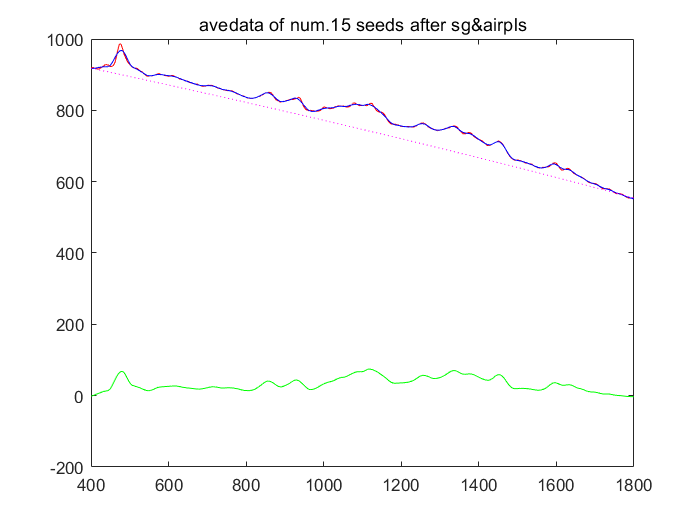

figure;
for i = 15
    plot(effshift, avedata(i, :), "Color", 'r')
    hold on;
    plot(effshift, avedata_sgfilter(i, :), "Color", 'b')
    hold on;
    plot(effshift, avedata_background(i, :), "Color", 'm', 'LineStyle', ":")
    hold on;
    plot(effshift, avedata_sg_airpls(i, :), "Color", 'g')   
end

title('avedata of num.15 seeds after sg&airpls')

## preprocessing ------ snv

tic

cube_sg_air_snv = zeros(efflines, effsamples, effbands);
for i = 1:efflines
    X = zeros(effsamples, effbands);
    X(:, :) = cube_sg_airpls(i, :, :);
    X_sg_air_snv = pre_snv(X);
    cube_sg_air_snv(i, :, : ) = X_sg_air_snv(:, :);
end

toc

历时 7.934014 秒。


tic
avedata_sg_air_snv = get_ave_spec(cube_sg_air_snv, bw_final);
toc

历时 39.589283 秒。


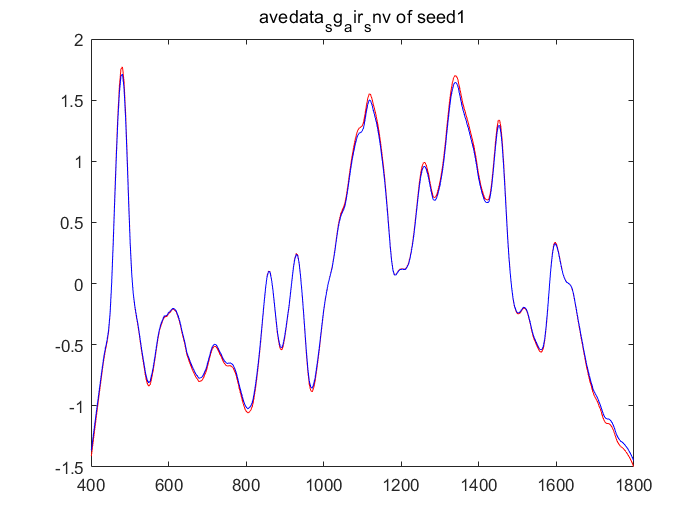

figure;
plot(effshift, avedata_sg_air_snv(1, :), "Color", 'r')
hold on;

plot(effshift, avedata_sg_air_snv_msc(1, :), "Color", 'b')
title('avedata_sg_air_snv of seed1')

## msc

avedata_sg_air_msc = pre_msc(avedata_sg_airpls, mean(avedata_sg_airpls, 1));

avedata_sg_air_snv_msc = pre_msc(avedata_sg_air_snv, mean(avedata_sg_air_snv, 1));

## 2nd dev

tic


cube_sg_air_snv_2nd = zeros(efflines, effsamples, effbands);
for i = 1:efflines
    X = zeros(effsamples, effbands);
    X(:, :) = cube_sg_air_snv(i, :, :);
    X_sg_air_snv_2nd = pre_sgfilter(X, 15, 2, 2);
    cube_sg_air_snv_2nd(i, :, : ) = X_sg_air_snv_2nd(:, :);
end

toc

历时 7.690707 秒。


tic
avedata_sg_air_snv_2nd = get_ave_spec(cube_sg_air_snv_2nd, bw_final);
toc

历时 36.355685 秒。


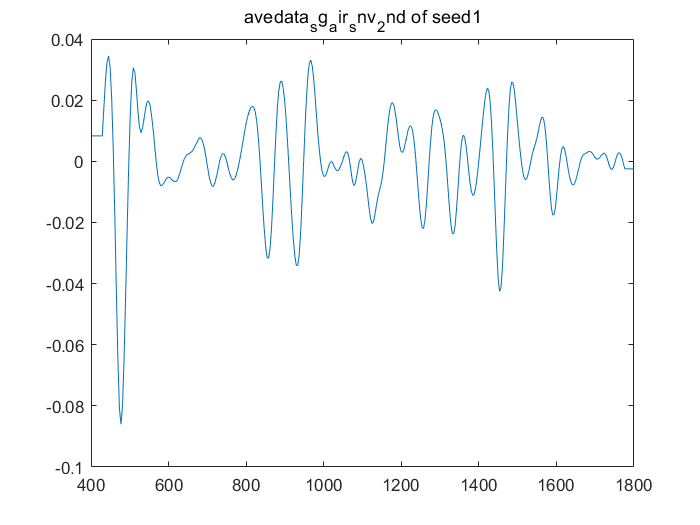

figure;
plot(effshift, avedata_sg_air_snv_2nd(1, :))
title('avedata_sg_air_snv_2nd of seed1')